# This live-script aim at plotting logarithmic density of image gradient.

## Load image and set parameters

clear; close all; clc;
img_src = imread('images\ceremony.jpg');
img_src_gray = rgb2gray(img_src);
g_max = 300;
rm_num = 100;
pts_num = 1500;

## Calculate gradient (method 1)

[grad_x, grad_y] = imgradientxy(img_src_gray);

## Calculate gradient (method 2)

partial_x = [1 -1];
partial_y = [1; -1];
% Do fourier transform
g_size = size(img_src_gray);
F_partial_x = fft2(partial_x, g_size(1), g_size(2));
F_partial_y = fft2(partial_y, g_size(1), g_size(2));
F_img_src_gray = fft2(img_src_gray);
grad_x_2 = real(ifft2(F_partial_x.*F_img_src_gray));
grad_y_2 = real(ifft2(F_partial_y.*F_img_src_gray));

## Process data X

x = reshape(grad_x_2, 1, []);
x = x ./ max(x) .* g_max;
pts = linspace(-g_max, g_max, pts_num);
[fx,xi] = ksdensity(x, pts);
fx = log10(fx);
for iter = 1:rm_num
    [~, fx_out_id] = min(fx);
    fx(fx_out_id) = [];
    xi(fx_out_id) = [];
end

## Plot x gradient

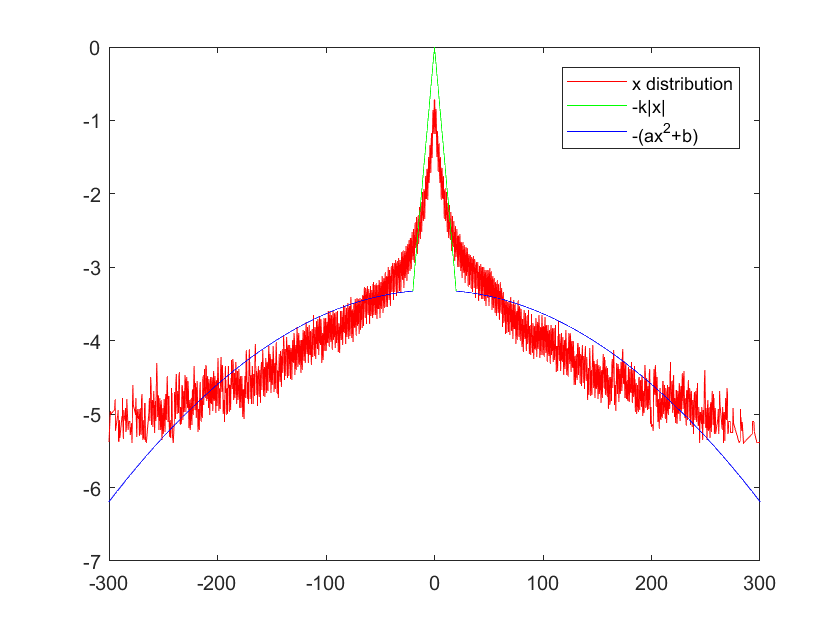

FIG_X = figure();
p_x = zeros(1,3);
p_x(1) = plot(xi,fx, 'r');
hold on;
% Fitting parameters:
l_t = 20;
l_t_f = -3.3248;
% parameters end.
% Linear fitting...
x_lin = linspace(0, l_t);
fx_lin = l_t_f/l_t .* x_lin;
p_x(2) = plot(x_lin, fx_lin, 'g');
hold on;
% Quadratic fitting...
[~, l_t_id] = min(abs(xi - l_t));
x_qua = xi(l_t_id:end);
fx_qua_data = fx(l_t_id:end);
a = 3.2e-05;
b = 3.312;
fx_qua = -(a .* x_qua .* x_qua + b);
p_x(3) = plot(x_qua, fx_qua, 'b');
plot(-x_lin, fx_lin, 'g', -x_qua, fx_qua, 'b');
legend(p_x(1:3), 'x distribution', '-k|x|', '-(ax^2+b)');

## Process data Y

y = reshape(grad_y_2, 1, []);
y = y ./ max(y) .* g_max;
pts = linspace(-g_max, g_max, pts_num);
[fy,yi] = ksdensity(y, pts);
fy = log10(fy);
for iter = 1:rm_num
    [fy_out, fy_out_id] = min(fy);
    fy(fy_out_id) = [];
    yi(fy_out_id) = [];
end

## Plot y gradient

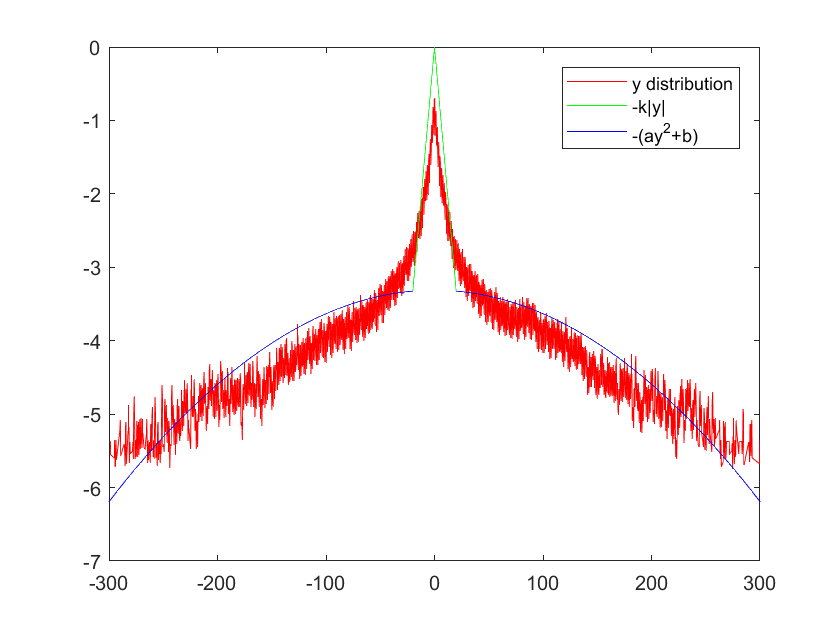

FIG_Y = figure();
p_y = zeros(1, 3);
p_y(1) = plot(yi,fy, 'r');
hold on;
% Linear fitting...
y_lin = linspace(0, l_t);
fy_lin = l_t_f/l_t .* x_lin;
p_y(2) = plot(y_lin, fy_lin, 'g');
hold on;
% Quadratic fitting...
[~, l_t_id] = min(abs(yi - l_t));
y_qua = yi(l_t_id:end);
fy_qua_data = fy(l_t_id:end);
a = 3.2e-05;
b = 3.312;
fy_qua = -(a .* y_qua.^2 + b);
p_y(3) = plot(y_qua, fy_qua, 'b');
plot(-y_lin, fy_lin, 'g', -y_qua, fy_qua, 'b');
legend(p_y(1:3), 'y distribution', '-k|y|', '-(ay^2+b)');